clc,clear, close all

%----------Information----------
disp("----------Information----------")

----------Information----------


syms x;

data=[ 5 , 106.8 ;
       8 , 177.2 ;
       12, 279.2 ; ]

data =     5.0000  106.8000
    8.0000  177.2000
   12.0000  279.2000



numOfData=size(data,1);
matrix= matrixMaker(data,numOfData)

matrix =    25.0000    5.0000    1.0000  106.8000
   64.0000    8.0000    1.0000  177.2000
  144.0000   12.0000    1.0000  279.2000



%----------Part A - Gauss Method----------

finalFunction1= gaussSolver(matrix,numOfData);

----------Gauss Method----------
  144.0000   12.0000    1.0000  279.2000
         0    2.9167    0.8264   58.3278
         0         0   -0.2000   -0.2171

results for guass method in order:
    0.2905   19.6905    1.0857




%----------Part B - Jacob Method----------

finalFunction2=jacobSolver(matrix,numOfData,[0,0,0],25);

----------Jacob Method----------
with Initail numbers 0  0  0 and 25 repeats.
results for jacob method in order:
   1.0e+14 *

    0.1210    0.5630    7.2589




%----------Part C - Lagrange Method----------

finalFunction3 = lagrangeSolver(data,numOfData);

----------Lagrange Method----------


$$\frac{349\,\left(x-5\right)\,\left(x-8\right)}{35}-\frac{443\,\left(x-5\right)\,\left(x-12\right)}{30}+\frac{178\,\left(x-8\right)\,\left(x-12\right)}{35}$$

$$\frac{61\,x^{2}}{210}+\frac{827\,x}{42}+\frac{38}{35}$$

results for lagrange method in order:
    0.2905   19.6905    1.0857




%----------Part D - Newton Method----------

finalFunction4=newtonSolver(data,numOfData);

----------Newton Method----------
    5.0000  106.8000         0         0
         0         0   23.4667         0
    8.0000  177.2000         0    0.2905
         0         0   25.5000         0
   12.0000  279.2000         0         0



$$\frac{352\,x}{15}+\frac{61\,\left(x-5\right)\,\left(x-8\right)}{210}-\frac{158}{15}$$

$$\frac{61\,x^{2}}{210}+\frac{827\,x}{42}+\frac{38}{35}$$

results for newton method in order:
    0.2905   19.6905    1.0857



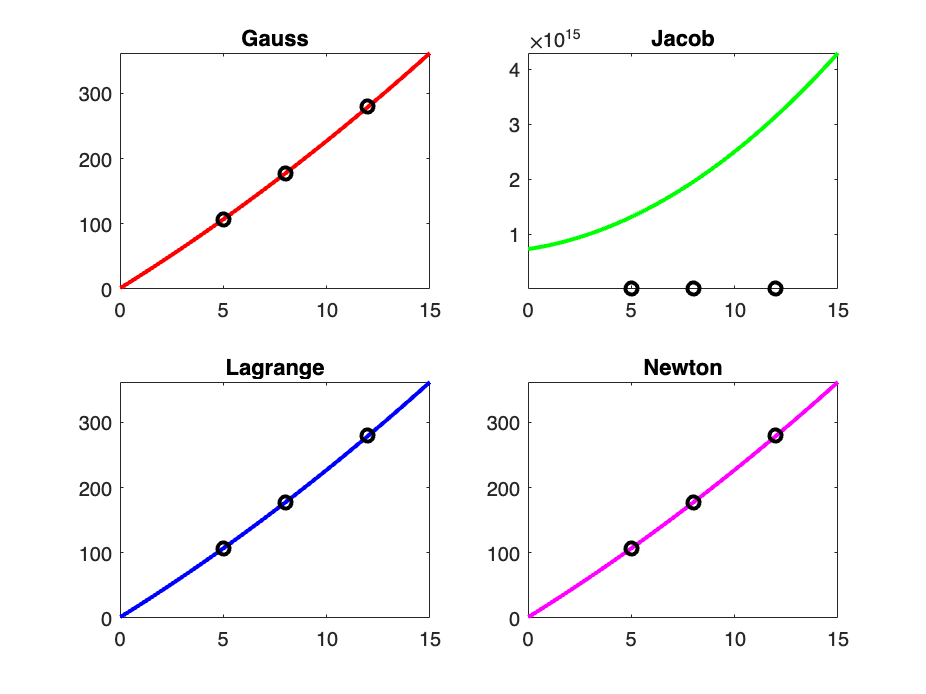


%--------Part E - Ploting------------
f1=figure;

x_dots=reshape(data(1:numOfData,1),[1,numOfData]);
y_dots=reshape(data(1:numOfData,2),[1,numOfData]);

subplot(2,2,1)
fplot(finalFunction1,[0,15],'r','LineWidth',2)
hold on
plot(x_dots,y_dots,'o','color','black','LineWidth',2);
title('Gauss')
subplot(2,2,2)
fplot(finalFunction2,[0,15],'g','LineWidth',2)
hold on
plot(x_dots,y_dots,'o','color','black','LineWidth',2);
title('Jacob')
subplot(2,2,3)
fplot(finalFunction3,[0,15],'b','LineWidth',2)
hold on
plot(x_dots,y_dots,'o','color','black','LineWidth',2);
title('Lagrange')
subplot(2,2,4)
fplot(finalFunction4,[0,15],'m','LineWidth',2)
hold on
plot(x_dots,y_dots,'o','color','black','LineWidth',2);
title('Newton')


%--------Part F - Speed in 10s------------

syms f(x)
funcs = [finalFunction1,finalFunction2,finalFunction3,finalFunction4];

for i=1:4
    f(x)=funcs(1,i);
    speedIn10= vpa(f(10),10)
end

$$speedIn10 = 227.0380952$$

$$speedIn10 = 2.498609341e+15$$

$$speedIn10 = 227.0380952$$

$$speedIn10 = 227.0380952$$


%--------Part G - New Data------------
disp("----------New Information----------")

----------New Information----------


data=[ 5 , 106.8 ;
       8 , 177.2 ;
       12, 279.2 ;
       6 , 129.6 ;]

data =     5.0000  106.8000
    8.0000  177.2000
   12.0000  279.2000
    6.0000  129.6000



numOfData=size(data,1);
matrix= matrixMaker(data,numOfData)

matrix = 1.0e+03 *

    0.1250    0.0250    0.0050    0.0010    0.1068
    0.5120    0.0640    0.0080    0.0010    0.1772
    1.7280    0.1440    0.0120    0.0010    0.2792
    0.2160    0.0360    0.0060    0.0010    0.1296



finalFunction1= gaussSolver(matrix,numOfData);

----------Gauss Method----------
   1.0e+03 *

    1.7280    0.1440    0.0120    0.0010    0.2792
         0    0.0213    0.0044    0.0007    0.0945
         0         0    0.0011    0.0004    0.0220
         0         0         0   -0.0000   -0.0001

results for guass method in order:
   -0.0071    0.4690   18.2905    4.5143



finalFunction2= jacobSolver(matrix,numOfData,[0,0,0,0],25);

----------Jacob Method----------
with Initail numbers 0  0  0  0 and 25 repeats.
results for jacob method in order:
   1.0e+16 *

    0.0309    0.1261    1.5496    4.9842



finalFunction3= lagrangeSolver(data,numOfData);

----------Lagrange Method----------


$$\frac{349\,\left(x-5\right)\,\left(x-6\right)\,\left(x-8\right)}{210}-\frac{443\,\left(x-5\right)\,\left(x-6\right)\,\left(x-12\right)}{60}+\frac{54\,\left(x-5\right)\,\left(x-8\right)\,\left(x-12\right)}{5}-\frac{178\,\left(x-6\right)\,\left(x-8\right)\,\left(x-12\right)}{35}$$

$$-\frac{x^{3}}{140}+\frac{197\,x^{2}}{420}+\frac{3841\,x}{210}+\frac{158}{35}$$

results for lagrange method in order:
   -0.0071    0.4690   18.2905    4.5143



finalFunction4= newtonSolver(data,numOfData);

----------Newton Method----------
    5.0000  106.8000         0         0         0
         0         0   23.4667         0         0
    8.0000  177.2000         0    0.2905         0
         0         0   25.5000         0   -0.0071
   12.0000  279.2000         0    0.2833         0
         0         0   24.9333         0         0
    6.0000  129.6000         0         0         0



$$\frac{352\,x}{15}+\frac{61\,\left(x-5\right)\,\left(x-8\right)}{210}-\frac{128674275067735\,\left(x-5\right)\,\left(x-8\right)\,\left(x-12\right)}{18014398509481984}-\frac{158}{15}$$

$$\frac{352\,x}{15}+\frac{61\,\left(x-5\right)\,\left(x-8\right)}{210}-\frac{128674275067735\,\left(x-5\right)\,\left(x-8\right)\,\left(x-12\right)}{18014398509481984}-\frac{158}{15}$$

results for newton method in order:
   -0.0071    0.4690   18.2905    4.5143




funcs = [finalFunction1,finalFunction2,finalFunction3,finalFunction4];

for i=1:4
    f(x)=funcs(1,i);
    speedIn10= vpa(f(10),10)
end

$$speedIn10 = 227.1809524$$

$$speedIn10 = 6.396979362e+17$$

$$speedIn10 = 227.1809524$$

$$speedIn10 = 227.1809524$$

function matrix = matrixMaker(data,numOfData)

    matrix= zeros(numOfData,numOfData+1);

    for i=(numOfData-1):-1:0
        matrix(1:numOfData,-i+numOfData)= (data(1:numOfData,1)).^(i);
    end

    matrix(1:numOfData,numOfData+1)= data(1:numOfData,2);
end

function finalFunction = gaussSolver(matrix,numOfData)
    disp("----------Gauss Method----------")
    syms x;
    gauss = matrix;

    for i=1:numOfData-1
    
        [~,finalIndex]= max(gauss(i:numOfData,1:numOfData+1));
        finalIndex=finalIndex(1,i)+i-1;
        holder = gauss(i,1:numOfData+1);
        gauss(i,1:numOfData+1)= gauss(finalIndex,1:numOfData+1);
        gauss(finalIndex,1:numOfData+1)= holder;
    
        for j=i+1:numOfData
            gauss(j,1:numOfData+1)= gauss(j,1:numOfData+1)-((gauss(j,i)/gauss(i,i))*gauss(i,1:numOfData+1));
        end
    end

    disp(gauss)
    
    result= zeros(1,numOfData);
    
    for i=numOfData:-1:1
        minus1=0;
        for j=1:(-i+numOfData)
            minus1= minus1+(gauss(i,-j+numOfData+1)*result(1,-j+numOfData+1));
        end
        minus1= -minus1;
        result(1,i)=(minus1+gauss(i,numOfData+1))/gauss(i,i);
    end
    
    finalFunction=0;
    for i=1:numOfData
        finalFunction= finalFunction+result(1,i)*(x^(-i+numOfData));
    end

    disp('results for guass method in order:');
    disp(result);  
end

function finalFunction = jacobSolver(matrix,numOfData,initialNumbers,repeats)
    disp("----------Jacob Method----------")
    disp(['with Initail numbers ',num2str(initialNumbers),' and ',num2str(repeats),' repeats.']);
    
    syms x;
    result=zeros(1,numOfData);
    jacob= matrix;
    
    for j=1:repeats
        for i=1:numOfData
            minus2=sum(jacob(i,1:numOfData).*initialNumbers)-(jacob(i,i)*initialNumbers(1,i));
            result(1,i)=(jacob(i,numOfData+1)-minus2)/jacob(i,i);
        end
        initialNumbers=result;
    end
    
    finalFunction=0;
    for i=1:numOfData
        finalFunction= finalFunction+result(1,i)*(x^(-i+numOfData));
    end

    disp("results for jacob method in order:");
    disp(result);
end

function finalFunction = lagrangeSolver(data,numOfData)
    disp("----------Lagrange Method----------")
    syms x;
    index= reshape(1:numOfData,[1,numOfData]);
    finalIndex= zeros(1,numOfData-1);
    finalFunction=0;
    
    for j= 1:numOfData
        up=1;
        down=1;
        finalIndex(1,1:j-1)=index(1,1:j-1);
        finalIndex(1,j:end)=index(1,j+1:end);
    
        for i=finalIndex
            up=up*(x-data(i,1));
            down=down*(data(j,1)-data(i,1));
        end
        finalFunction=finalFunction+((up/down)*data(j,2));
    end
    
    disp(finalFunction);
    finalFunction=simplify(finalFunction);
    disp(finalFunction)
    result= sym2poly(finalFunction);
    disp("results for lagrange method in order:")
    disp(result)  
end

function finalFunction = newtonSolver(data,numOfData)
    disp("----------Newton Method----------")
    syms x;
    newton=zeros(2*numOfData-1,1+numOfData);
    newton(1:2:2*numOfData-1,2)=data(1:numOfData,2);
    newton(1:2:2*numOfData-1,1)=data(1:numOfData,1);
    
    for j=3:numOfData+1
        for i= j-1:2:-j+(2*numOfData+1)
            newton(i,j)= (newton(i+1,j-1)-newton(i-1,j-1))/(newton(i+j-2,1)-newton(i-j+2,1));
        end
    end
    
    disp(newton);
    finalFunction=data(1,2);
    
    for i=1:numOfData-1
        cross=1;
        for j=1:i
            cross=cross*(x-data(j,1));
        end
        
        finalFunction= finalFunction+(cross*newton(i+1,2+i));
    end

    disp(finalFunction)
    finalFunction=simplify(finalFunction);
    disp(finalFunction)
    result= sym2poly(finalFunction);
    disp("results for newton method in order:")
    disp(result);
end